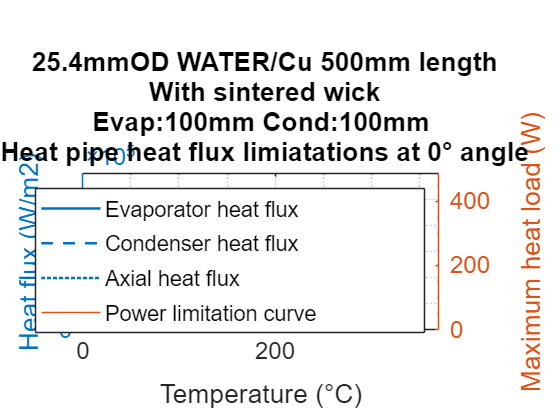

%%%%%%%%%%%%%%%%%%%%  Graph 7: Heat flux

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Create Figure 7: Heat Flux Graphs %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure7 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure7);
hold(axes1,'on');

yyaxis left
plot1 = plot(T(:,1),[q_evap,q_cond,q_axial],'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);
set(plot1(2),'DisplayName','Condenser heat flux','LineWidth',2);
set(plot1(3),'DisplayName','Axial heat flux','LineWidth',2);

ylabel({'Heat flux (W/m2)'});   

yyaxis right
plot1 = plot(T(:,1),Q_min,'Parent',axes1);
set(plot1(1),'DisplayName','Power limitation curve');


ylabel({'Maximum heat load (W)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});     

xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')